# Digits Data Neural Network

For this network we will use the extrated features, symmetry and intensity, of the MNIST dataset.

clearvars
load('usps_modified.mat');  % load raw image dataset, modified to remove image slant
[x,y] = getfeatures(data);  % run feature extration for intensity and symmetry
y(y~=1) = 0;                % label digit 1 as '1', all other digits as '0'

Setup training and test sets.

[n, d] = size(x);                   % get the number of data points and dimensionality
dout = width(y);                    % get the number of output nodes
indx = randperm(n);                 % setup a random ordering of the data
xtrain = x(indx(1:floor(0.8*n)),:);     ytrain = y(indx(1:floor(0.8*n)));   % training set
xtest = x(indx(floor(0.8*n)+1:n),:);    ytest = y(indx(floor(0.8*n)+1:n));  % test set

## Network Setup

We will create a simple neural network with a single hidden layer with 5 nodes and a single node output layer. Defining the network is as simple as setting the weight matrices.

First set a parameter for each layer dimension and initialize the network structure

dims = [d 5 dout];
nnmethod = 'steepest'; % 'stochastic' 'batch' 'variable' 'steepest'
num_layers = length(dims);
layers(1:num_layers,1) = struct;

### Initial Weight Matrices

for i = 2:num_layers
    layers(i).w = rand(dims(i-1)+1,dims(i));
end

## Training the Network

methods = ["stochastic" "batch" "variable" "steepest"];
ksize = 10;
emax = 1000;
ein_table = zeros(4, ksize);
plot_table = zeros(4, emax);
for m = 1:4
    nnmethod = methods(m);
    for k = 1:ksize
        eta = 0.1;
        epoch = 1;
        ntrain = length(xtrain);
        Ein = zeros(emax,1);
        while epoch <= emax
            switch nnmethod
                case 'stochastic'
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        for l = 2:num_layers            % update the weights after each data point
                            layers(l).w = layers(l).w-(eta*layers(l).grad);
                        end
                        Ein(epoch) = 0.5*pow2(layers(num_layers).x(2) - y(i));
                    end
                case 'batch'
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        Ein(epoch) = Ein(epoch) + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
                        for l = 2:num_layers
                            layers(l).G = -(sum(layers(l).grad)/ntrain);
                        end
                    end
                    for l = 2:num_layers            % update the weights after batch update
                        layers(l).w = layers(l).w-(eta*layers(l).grad); 
                    end
                case 'variable'
                    % run batch
                    Ein_a = 0;
                    alpha = 1.075;
                    beta = 0.65;
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        Ein(epoch) = Ein(epoch) + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
                        for l = 2:num_layers
                            layers(l).G = -(sum(layers(l).grad)/ntrain);
                        end
                    end
                    for l = 2:num_layers            % update the weights after batch update
                        layers(l).w = layers(l).w-(eta*layers(l).grad); 
                    end
                    % descend
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        Ein_a = Ein_a + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
                    end
                    if Ein_a < Ein
                        % update weights again
                        for l = 2:num_layers            % update the weights after batch update
                            layers(l).w = layers(l).w-(eta*layers(l).grad); 
                        end
                        Ein(epoch) = Ein_a;
                        eta = alpha * eta;
                    else
                        eta = beta * eta;
                    end
                case 'steepest'
                    Ein_a = 0;
                    % batch first
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        Ein(epoch) = Ein(epoch) + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
                        for l = 2:num_layers
                            layers(l).G = -(sum(layers(l).grad)/ntrain);
                        end
                    end
                    for l = 2:num_layers            % update the weights after batch update
                        layers(l).w = layers(l).w-(eta*layers(l).grad); 
                    end
                    % initial U-arrangement
                    epsi = eta;
                    Uarr = [0 eta 2*eta]; % [0 epsi 0]
                    EU = [0 0 0]; % error array
                    EU(1) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(1));
                    EU(2) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(2));
                    EU(3) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(3));
                    if EU(2) < EU(1)
                        Uarr(3) = 2*Uarr(2);
                    elseif EU(2) > EU(1)
                            Uarr(1) = Uarr(2);
                            Uarr(2) = 0;
                            Uarr(3) = -epsi;
                    end
                    % infinite loop
                   % while EU(3) < EU(2)
                   %     Uarr(1) = Uarr(2);
                   %     Uarr(2) = Uarr(3);
                   %     Uarr(3) = 2 * Uarr(3);
                   %     EU(2) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(2));
                   %     EU(3) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(3));
                   % end
                    % line search
                    neta = 0;
                   % for i=1:10
                   %     neta = 0.5*(Uarr(1) + Uarr(3));
                   %     err_neta = batch_err(x, y, layers, num_layers, n, ntrain, neta);
                   %     EU(2) = batch_err(x, y, layers, num_layers, n, ntrain, Uarr(2));
                   %     if err_neta < EU(2)
                   %         if err_neta < EU(2)
                   %             Uarr = [Uarr(1) neta Uarr(2)];
                   %         elseif err_neta > EU(2)
                   %             Uarr = [neta Uarr(2) Uarr(3)];
                   %         end
                   %     elseif neta < Uarr(2)
                   %         if err_neta < EU(2)
                   %             Uarr = [Uarr(2) neta Uarr(3)];
                   %         elseif err_neta > EU(2)
                   %             Uarr = [Uarr(1) Uarr(2) neta];
                   %         end
                   %     else
                   %         neta = neta*1.05;
                   %     end
                   % end
                    % do it again
                    for i = 1:ntrain
                        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
                        layers = runnetwork(layers,y(i));
                        Ein(epoch) = Ein(epoch) + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
                        for l = 2:num_layers
                            layers(l).G = -(sum(layers(l).grad)/ntrain);
                        end
                    end
                    for l = 2:num_layers            % update the weights after batch update
                        layers(l).w = layers(l).w-(eta*layers(l).grad); 
                    end
            end
            % error calculations here, potentially
            epoch = epoch + 1;
        end
        ein_table(m,k,:) = Ein(emax);
    end
    plot_table(m,:) = Ein;
end

## Difficulties

The most difficulty for me came from understanding the math and applying it to matlab. I've written a neural networks for a previous class without any issues, but I struggled too much with this one. The line search was especially difficult. Another struggle was runtime. I'm not sure whether it's the efficiency of my code or the power of my computer, but the program takes forever to run.

## Results

The neural network seems to perform quite poorly. For Everything but steepest descent, error is about 40-50% initially and hardly changes oever 100 epochs. However, this might just be a side effect of slow learning. I've been unable to test the network with enough epochs to make a significant difference. My computer or the algorithm is simply too slow. With a learning rate of 0.1, the error does show signs of decreasing over 10 epochs, though only a few tenths of a percent. Even just 1000 epochs is unable to complete in under an hour. As for steepest descent, even just one run of 10 epochs wasn't able to complete in a reasonable amount of time, so I commented out the main loops and logic. An error of 80% is thus not very surprising.

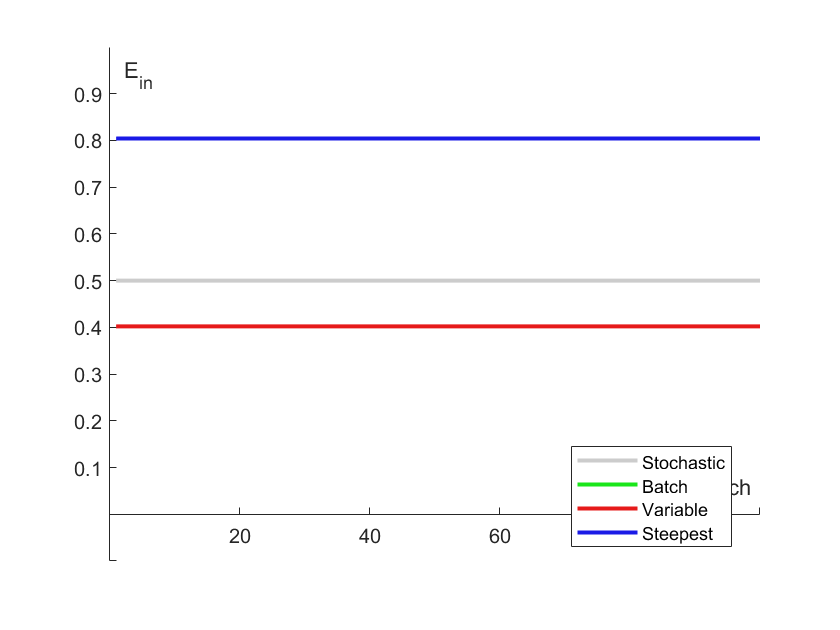

% plot for all 4
plot_err(plot_table);

% average error over k runs each
ein_table'

ans =     0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043
    0.5000    0.4022    0.4022    0.8043


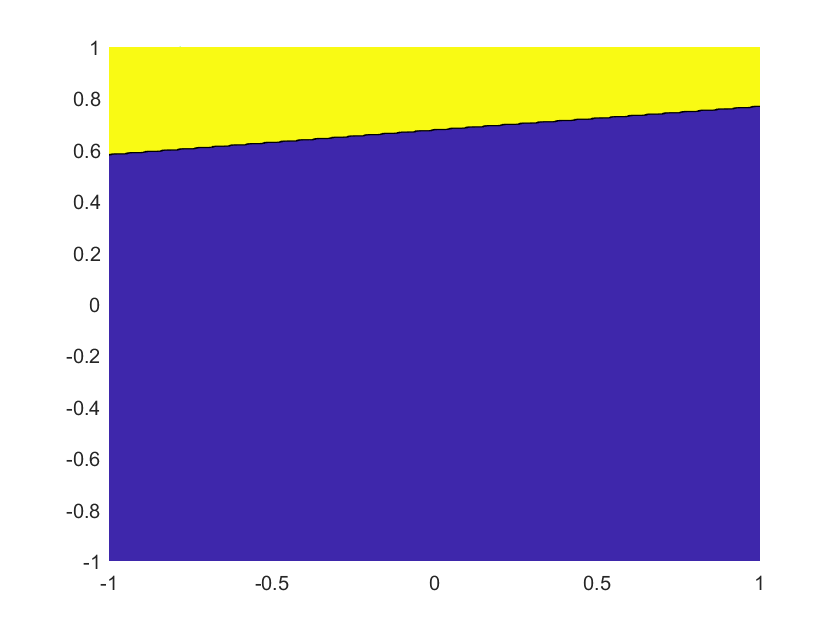

% map of classification space
cplot(xtrain, ytrain, layers, num_layers);

## Supporting Functions

Run Neural Network Function

function [layers] = runnetwork(layers,y)
    layers = fwdprop(layers);
    layers = backprop(layers,y);
    layers = getnngrad(layers);
end

Forward Propagation Function

function [ layers ] = fwdprop( layers )
% FWDPROP Propagate through a neural network
%   by calculating the signals and outputs of each
%   layer. Single data point input is assumed. 
%   INPUTS:
%       layers.x:   input data point including bias (x_0)
%       layers:     struct array of layer weights - layer(l).w 
%   RETURN:
%       layers: filled in struct array of signals - layer(l).s, and
%           outputs - layer(l).x

num_layers = length(layers);                % get number of layers in network

theta = @(x) 1./(1+exp(-1*x));                      % logistic function
%theta = @(x) (exp(x)-exp(-x))./(exp(x)+exp(-x));    % tanh function

for l = 2:num_layers
    layers(l).s = layers(l).w'*layers(l-1).x;       % calculate signal
    layers(l).x = [1; theta(layers(l).s)];          % calculate output
end
end

Back-Propagation Algorithm

function [ layers ] = backprop( layers,y )
% backprop Calculates sensitivity values in a network
%   Propagating backwards through the network, calculate the delta
%   (sensitivity values), based on the target value y

thetap = @(x) x.*(1-x);    % derivative of logistic function (1/1-e^-s)
%thetap = @(x) 1-(x.*x);    % derivative of the tanh function 

num_layers = length(layers);

x = layers(num_layers).x(2:length(layers(num_layers).x));   % remove bias
layers(num_layers).del = thetap(x).*(x - y);                % initialize last layer

for  l = num_layers-1:-1:2
    x = layers(l).x(2:length(layers(l).x));             % remove the bias 
    w = layers(l+1).w(2:length(layers(l+1).w));         % remove bias weight
    layers(l).del = thetap(x).*(w * layers(l+1).del);   % get next delta
end

end

Error Gradient Calculation Function

function [ layers ] = getnngrad( layers )
% getnngrad Calculates the error gradient for each layer
%   of the neural net. Assumes forward and backpropagation 
%   has already been completed.

num_layers = length(layers);

for l = 2:num_layers
    layers(l).grad = layers(l-1).x*layers(l).del';
end
end

Batch Function

function Ein = batch_err(x, y, layers, num_layers, n, ntrain, eta)
    for l = 2:num_layers            % update the weights after batch update
        layers(l).w = layers(l).w-(eta*layers(l).grad); 
    end
    Ein = 0;
    for i = 1:ntrain
        layers(1).x = [1; x(i,:)'];     % get i-th data point, add leading 1
        layers = runnetwork(layers,y(i));
        Ein = Ein + (1/(2*n))*pow2(layers(num_layers).x(2) - y(i));
    end
end

Plot Ein x epoch

function [] = plot_err(ein_table)
    figure();
    n = width(ein_table);
    hold on;
    axis([-0.1 n -0.1 1]);
    xlabel('Epoch');
    ylabel('E_{in}');
    ax = gca;
    ax.XAxisLocation='origin';
    ax.YAxisLocation='origin';
    x1 = 1:n;
    plot(x1, ein_table(1,:), 'Color',[.8 .8 .8], 'LineStyle', '-','LineWidth',2, 'DisplayName','Stochastic');
    plot(x1, ein_table(2,:), 'Color',[.1 .9 .1], 'LineStyle', '-','LineWidth',2, 'DisplayName','Batch');
    plot(x1, ein_table(3,:), 'Color',[.9 .1 .1], 'LineStyle', '-','LineWidth',2, 'DisplayName','Variable');
    plot(x1, ein_table(4,:), 'Color',[.1 .1 .9], 'LineStyle', '-','LineWidth',2, 'DisplayName','Steepest');
    legend('Location', 'best');
end

Contour Plot

function [] = cplot(x, y, layers, num_layers)
    figure();
    hold on;
    for i = 1:height(y)
        if y(i) == -1
            scatter(x(i,1),x(i,2),'r','+','LineWidth',2, 'DisplayName', 'Ones');
        else
            scatter(x(i,1),x(i,2),'g','O','LineWidth',2, 'DisplayName', 'Others');
        end
    end
    [x1,x2] = meshgrid(-1:0.005:1);
    for i = 1:length(x1)
        for j = 1:width(x2)
            layers(1).x = [1; x1(i,j); x2(i,j)];
            layers = fwdprop(layers);
            z(i,j) = layers(num_layers).x(2);
        end
    end
    contourf(x1,x2,z,[0 0.7 0.9],'DisplayName','Classification Map')
    %legend('Location', 'best');
end